% Setup parameters
clear; close all; clc;
load("cooplocalization_finalproj_KFdata.mat");

% System parameters
vg = 2;           % UGV velocity [m/s]
phi_g = -pi/18;   % UGV steering angle [rad]
va = 12;          % UAV velocity [m/s]
wa = pi/25;       % UAV angular velocity [rad/s]
L = 0.5;          % UGV wheelbase [m]

% Nominal state trajectories
xi_g_nom = @(t) (1/(2*tan(pi/18))) * (20*tan(pi/18) + 1 - cos(4*tan(phi_g)*t));
eta_g_nom = @(t) (1/(2*tan(pi/18))) * sin(4*tan(phi_g)*t);
theta_g_nom = @(t) pi/2 + 4*tan(phi_g)*t;

xi_a_nom = @(t) (1/pi)*(300 - 60*t - 300*cos(pi/25*t));
eta_a_nom = @(t) (300/pi)*sin(pi/25*t);
theta_a_nom = @(t) wrapToPi(-pi/2 + pi/25*t);

% Full nominal state
nominal_state = @(t) [xi_g_nom(t); eta_g_nom(t); theta_g_nom(t); 
                      xi_a_nom(t); eta_a_nom(t); theta_a_nom(t)];

% Initial perturbation and covariance
dx0 = [0.1; 0.1; 0.05; 0.1; 0.1; 0.05];

% Process noise covariance scaling
Q = Qtrue;
R = Rtrue;  % Use the provided measurement noise covariance

% Monte Carlo Simulation Parameters
Nsims = 50;  % Increased from 50 for better statistical significance
T = 10;       % Simulation time in seconds
dt = 0.1;     % Time step
time = 0:dt:T;
steps = length(time);
n = 6;        % State dimension
p = 5;        % Measurement dimension

NEESsamps_lkf = zeros(Nsims, steps);
NISsamps_lkf = zeros(Nsims, steps);
NEESsamps_ekf = zeros(Nsims, steps);
NISsamps_ekf = zeros(Nsims, steps);

% More conservative initial covariance
P0 = diag([
    2.0^2,          % Increased initial position uncertainty
    2.0^2,          
    (pi/4)^2,       % Increased angular uncertainty
    2.5^2,          % Larger uncertainty for UAV
    2.5^2,          
    (pi/4)^2
]);

% Process noise tuning - scale up from true noise
Q_kf = Qtrue;                 % More conservative process noise estimate
x_lkf(:,1) = nominal_state(0) + dx0;      % Start at nominal
dx0 = zeros(6,1);                   % Initialize deviation as zero
P_lkf(:,:,1) = P0;                  % Initial uncertainty

% Monte Carlo simulation loop
for sim = 1:Nsims
    fprintf('Running simulation %d of %d\n', sim, Nsims);
    
    % Initialize true trajectory with random perturbation
    x_true = zeros(n, steps);
    x0_err = mvnrnd(zeros(n,1), P0)';
    x_true(:,1) = nominal_state(0) + x0_err;
    
    % Initialize filter states
    x_lkf = zeros(n, steps);
    P_lkf = zeros(n, n, steps);
    x_ekf = zeros(n, steps);
    P_ekf = zeros(n, n, steps);
    
    % Initialize filters at nominal state
    x_lkf(:,1) = nominal_state(0);
    P_lkf(:,:,1) = P0;
    x_ekf(:,1) = nominal_state(0);
    P_ekf(:,:,1) = P0;
    
    % Storage for measurements
    y = zeros(p, steps);
    
    % Generate true trajectory and measurements
    for k = 1:steps-1
        % Generate state-dependent process noise
        Q_true_k = generate_state_dependent_noise(x_true(:,k), vg, va, phi_g, wa, L, dt);
        w = mvnrnd(zeros(n,1), Q_true_k)';
        
        % Propagate true state with nonlinear dynamics
        dx = system_dynamics(x_true(:,k), vg, va, phi_g, wa, L);
        x_true(:,k+1) = x_true(:,k) + dt*dx + w;
        
        % Ensure proper angle wrapping
        x_true([3,6],k+1) = wrapToPi(x_true([3,6],k+1));
        
        % Generate measurement with state-dependent noise
        R_k = generate_measurement_noise(x_true(:,k+1), Rtrue);
        v = mvnrnd(zeros(p,1), R_k)';
        y(:,k) = measurement_model(x_true(:,k+1)) + v;
    end
    
    % Run filters
    for k = 1:steps-1
        % Get nominal states for LKF
        x_nom_curr = nominal_state(time(k));
        x_nom_next = nominal_state(time(k+1));
        
        % === LKF Prediction ===
        Q_lkf_k = generate_state_dependent_noise(x_lkf(:,k), vg, va, phi_g, wa, L, dt);
        [x_lkf_pred, P_lkf_pred] = lkf_predict(x_lkf(:,k), P_lkf(:,:,k), ...
            x_nom_curr, dt, Q_lkf_k, vg, va);
            
        % === EKF Prediction ===
        Q_ekf_k = generate_state_dependent_noise(x_ekf(:,k), vg, va, phi_g, wa, L, dt);
        [x_ekf_pred, P_ekf_pred] = ekf_predict(x_ekf(:,k), P_ekf(:,:,k), ...
            dt, Q_ekf_k, vg, va, phi_g, wa, L);
        
        % === Measurement Updates ===
        % Generate state-dependent measurement noise
        R_lkf_k = generate_measurement_noise(x_lkf_pred, Rtrue);
        R_ekf_k = generate_measurement_noise(x_ekf_pred, Rtrue);
        
        % LKF Update
        [x_lkf(:,k+1), P_lkf(:,:,k+1), innov_lkf, S_lkf] = ...
            lkf_update(x_lkf_pred, P_lkf_pred, y(:,k), x_nom_curr, R_lkf_k);
            
        % EKF Update
        [x_ekf(:,k+1), P_ekf(:,:,k+1), innov_ekf, S_ekf] = ...
            ekf_update(x_ekf_pred, P_ekf_pred, y(:,k), R_ekf_k);
        
        % Ensure proper angle wrapping
        x_lkf([3,6],k+1) = wrapToPi(x_lkf([3,6],k+1));
        x_ekf([3,6],k+1) = wrapToPi(x_ekf([3,6],k+1));
        
        % Check covariance matrix consistency
        check_covariance_consistency(P_lkf(:,:,k+1), 'LKF', k);
        check_covariance_consistency(P_ekf(:,:,k+1), 'EKF', k);
        
        % === Performance Metrics ===
        % NEES computation with proper angle wrapping
        err_lkf = x_true(:,k) - x_lkf(:,k);
        err_lkf([3,6]) = wrapToPi(err_lkf([3,6]));
        NEESsamps_lkf(sim,k) = err_lkf' / P_lkf(:,:,k) * err_lkf;
        
        err_ekf = x_true(:,k) - x_ekf(:,k);
        err_ekf([3,6]) = wrapToPi(err_ekf([3,6]));
        NEESsamps_ekf(sim,k) = err_ekf' / P_ekf(:,:,k) * err_ekf;
        
        % NIS computation with proper angle wrapping
        NISsamps_lkf(sim,k) = compute_nis(innov_lkf, S_lkf);
        NISsamps_ekf(sim,k) = compute_nis(innov_ekf, S_ekf);
    end
end

Running simulation 1 of 50
Running simulation 2 of 50
Running simulation 3 of 50
Running simulation 4 of 50
Running simulation 5 of 50
Running simulation 6 of 50
Running simulation 7 of 50
Running simulation 8 of 50
Running simulation 9 of 50
Running simulation 10 of 50
Running simulation 11 of 50
Running simulation 12 of 50
Running simulation 13 of 50
Running simulation 14 of 50
Running simulation 15 of 50
Running simulation 16 of 50
Running simulation 17 of 50
Running simulation 18 of 50
Running simulation 19 of 50
Running simulation 20 of 50
Running simulation 21 of 50
Running simulation 22 of 50
Running simulation 23 of 50
Running simulation 24 of 50
Running simulation 25 of 50
Running simulation 26 of 50
Running simulation 27 of 50
Running simulation 28 of 50
Running simulation 29 of 50
Running simulation 30 of 50
Running simulation 31 of 50
Running simulation 32 of 50
Running simulation 33 of 50
Running simulation 34 of 50
Running simulation 35 of 50
Running simulation 36 of 50
R

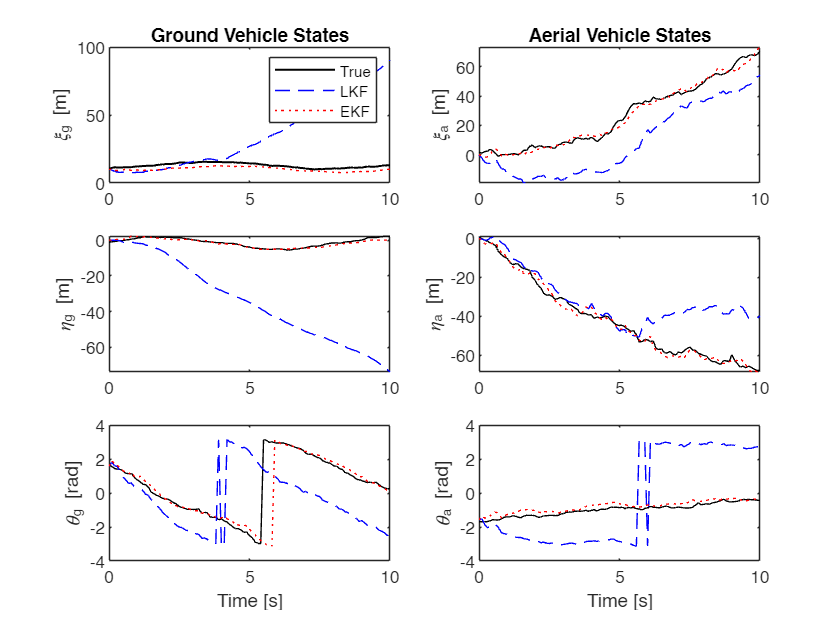


% Compute NEES/NIS statistics
alpha = 0.05;  % 95% confidence interval

% For NEES bounds
r1_nees = chi2inv(alpha/2, n)/Nsims;        % Lower bound
r2_nees = chi2inv(1-alpha/2, n)/Nsims;      % Upper bound

% For NIS bounds
r1_nis = chi2inv(alpha/2, p)/Nsims;         % Lower bound
r2_nis = chi2inv(1-alpha/2, p)/Nsims;       % Upper bound

% Compute mean values
mean_NEES_lkf = mean(NEESsamps_lkf, 1);
mean_NEES_ekf = mean(NEESsamps_ekf, 1);

mean_NIS_lkf = mean(NISsamps_lkf, 1);
mean_NIS_ekf = mean(NISsamps_ekf, 1);

% Create visualization figures
figure('Name', 'State Estimation Results');
subplot(3,2,1)
plot(time, x_true(1,:), 'k', 'LineWidth', 1)
hold on
plot(time, x_lkf(1,:), 'b--', time, x_ekf(1,:), 'r:')
ylabel('\xi_g [m]')
title('Ground Vehicle States')
legend('True', 'LKF', 'EKF')

subplot(3,2,3)
plot(time, x_true(2,:), 'k', time, x_lkf(2,:), 'b--', time, x_ekf(2,:), 'r:')
ylabel('\eta_g [m]')

subplot(3,2,5)
plot(time, x_true(3,:), 'k', time, x_lkf(3,:), 'b--', time, x_ekf(3,:), 'r:')
ylabel('\theta_g [rad]')
xlabel('Time [s]')

subplot(3,2,2)
plot(time, x_true(4,:), 'k', time, x_lkf(4,:), 'b--', time, x_ekf(4,:), 'r:')
ylabel('\xi_a [m]')
title('Aerial Vehicle States')

subplot(3,2,4)
plot(time, x_true(5,:), 'k', time, x_lkf(5,:), 'b--', time, x_ekf(5,:), 'r:')
ylabel('\eta_a [m]')

subplot(3,2,6)
plot(time, x_true(6,:), 'k', time, x_lkf(6,:), 'b--', time, x_ekf(6,:), 'r:')
ylabel('\theta_a [rad]')
xlabel('Time [s]')

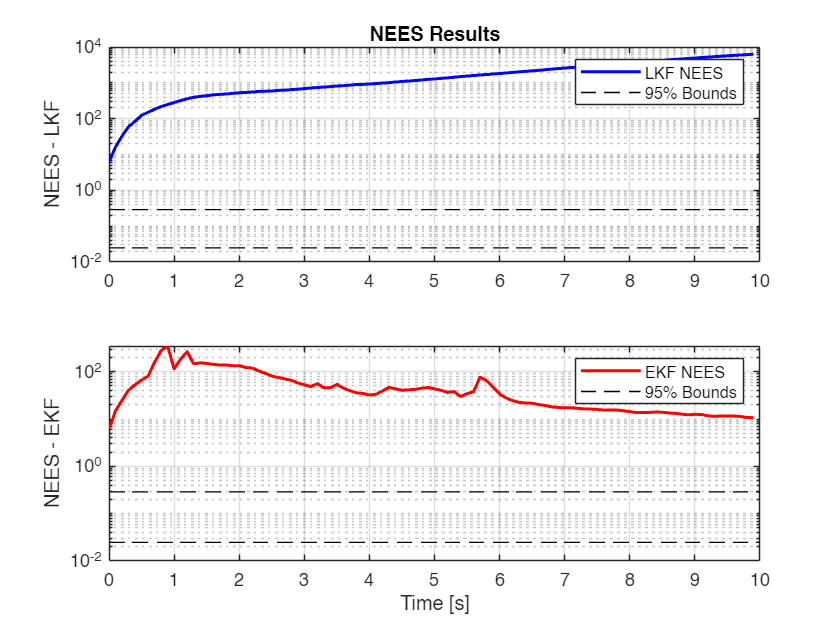


% NEES Results
figure('Name', 'NEES Analysis');
subplot(2,1,1)
semilogy(time, mean(NEESsamps_lkf), 'b-', 'LineWidth', 1.5)
hold on
semilogy(time, r1_nees*ones(size(time)), 'k--', time, r2_nees*ones(size(time)), 'k--')
ylabel('NEES - LKF')
title('NEES Results')
grid on
legend('LKF NEES', '95% Bounds')

subplot(2,1,2)
semilogy(time, mean(NEESsamps_ekf), 'r-', 'LineWidth', 1.5)
hold on
semilogy(time, r1_nees*ones(size(time)), 'k--', time, r2_nees*ones(size(time)), 'k--')
ylabel('NEES - EKF')
xlabel('Time [s]')
grid on
legend('EKF NEES', '95% Bounds')

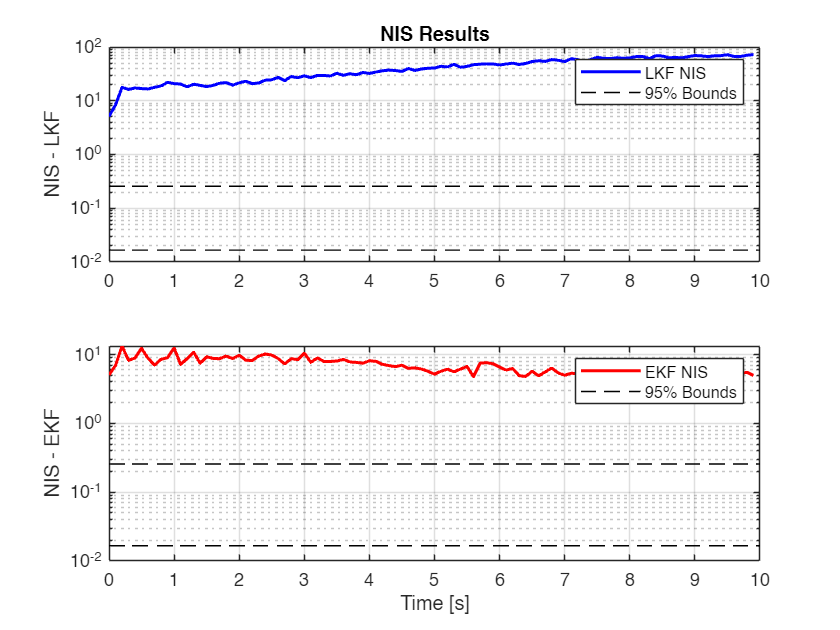


% NIS Results
figure('Name', 'NIS Analysis');
subplot(2,1,1)
semilogy(time, mean(NISsamps_lkf), 'b-', 'LineWidth', 1.5)
hold on
semilogy(time, r1_nis*ones(size(time)), 'k--', time, r2_nis*ones(size(time)), 'k--')
ylabel('NIS - LKF')
title('NIS Results')
grid on
legend('LKF NIS', '95% Bounds')

subplot(2,1,2)
semilogy(time, mean(NISsamps_ekf), 'r-', 'LineWidth', 1.5)
hold on
semilogy(time, r1_nis*ones(size(time)), 'k--', time, r2_nis*ones(size(time)), 'k--')
ylabel('NIS - EKF')
xlabel('Time [s]')
grid on
legend('EKF NIS', '95% Bounds')

function y = measurement_model(x)
    % Extract states
    xi_g = x(1); eta_g = x(2); theta_g = x(3);
    xi_a = x(4); eta_a = x(5); theta_a = x(6);
    
    % Compute relative vector
    dx = xi_a - xi_g;
    dy = eta_a - eta_g;
    
    % Compute range with numerical stability
    range = max(sqrt(dx^2 + dy^2), 1e-6);
    
    % Compute bearings with careful wrapping
    bearing1 = wrapToPi(atan2(dy, dx) - theta_g);
    bearing2 = wrapToPi(atan2(-dy, -dx) - theta_a);
    
    y = [bearing1; range; bearing2; xi_a; eta_a];
end

% Modified measurement Jacobian
function H = measurement_jacobian(x)
    % Extract states
    xi_g = x(1); eta_g = x(2);
    xi_a = x(4); eta_a = x(5);
    
    % Compute common terms
    dx = xi_a - xi_g;
    dy = eta_a - eta_g;
    r = max(sqrt(dx^2 + dy^2), 1e-6);
    r2 = r^2;
    
    % Initialize H matrix
    H = zeros(5,6);
    
    % Bearing 1 derivatives
    H(1,1) = dy/r2;
    H(1,2) = -dx/r2;
    H(1,3) = -1;
    H(1,4) = -dy/r2;
    H(1,5) = dx/r2;
    
    % Range derivatives
    H(2,1) = -dx/r;
    H(2,2) = -dy/r;
    H(2,4) = dx/r;
    H(2,5) = dy/r;
    
    % Bearing 2 derivatives
    H(3,1) = -dy/r2;
    H(3,2) = dx/r2;
    H(3,4) = dy/r2;
    H(3,5) = -dx/r2;
    H(3,6) = -1;
    
    % GPS measurements
    H(4:5,4:5) = eye(2);
end

function [x_pred, P_pred] = lkf_predict(x, P, x_nom_curr, dt, Q, vg, va)
    % Compute the state transition matrix using the nominal state
    F = eye(6) + dt * [
        0, 0, -vg*sin(x_nom_curr(3)), 0, 0, 0;
        0, 0,  vg*cos(x_nom_curr(3)), 0, 0, 0;
        0, 0,  0, 0, 0, 0;
        0, 0,  0, 0, 0, -va*sin(x_nom_curr(6));
        0, 0,  0, 0, 0,  va*cos(x_nom_curr(6));
        0, 0,  0, 0, 0,  0
    ];
    
    % For the LKF, we're tracking deviations from the nominal trajectory
    % The nominal dynamics are already known from the nominal_state function
    % We just need to propagate the current state estimate using F
    
    x_pred = F * x;

    P_pred = F * P * F' + Q;
    P_pred = (P_pred + P_pred')/2;
end

function [x_new, P_new, innov, S] = lkf_update(x_pred, P_pred, y, x_nom, R)
    % Compute nominal measurement
    y_nom = measurement_model(x_nom);
    
    % Get measurement matrix at nominal point
    H = measurement_jacobian(x_nom);
    
    % Predict measurement deviation
    dx = x_pred - x_nom;
    dy_pred = H * dx;
    
    % Total predicted measurement
    y_pred = y_nom + dy_pred;
    
    % Innovation with angle wrapping
    innov = y - y_pred;
    innov([1,3]) = wrapToPi(innov([1,3]));
    
    % Update step
    S = H * P_pred * H' + R;
    K = P_pred * H' / (S + 1e-8*eye(size(S)));
    
    % Update state and covariance
    dx_new = dx + K * innov;
    x_new = x_nom + dx_new;
    x_new([3,6]) = wrapToPi(x_new([3,6]));
    
    % Joseph form for covariance update
    I = eye(size(P_pred));
    P_new = (I - K*H) * P_pred * (I - K*H)' + K*R*K';
end

function [x_pred, P_pred] = ekf_predict(x, P, dt, Q, vg, va, phi_g, wa, L)
    % Predict state using nonlinear dynamics
    dx = system_dynamics(x, vg, va, phi_g, wa, L);
    x_pred = x + dt*dx;
    
    % Compute Jacobian
    F = eye(6) + dt * [
        0, 0, -vg*sin(x(3)), 0, 0, 0;
        0, 0,  vg*cos(x(3)), 0, 0, 0;
        0, 0,  0, 0, 0, 0;
        0, 0,  0, 0, 0, -va*sin(x(6));
        0, 0,  0, 0, 0,  va*cos(x(6));
        0, 0,  0, 0, 0,  0
    ];
    
    P_pred = F * P * F' + Q;
end

function [x_new, P_new, innov, S] = ekf_update(x_pred, P_pred, y, R)
    % Compute measurement Jacobian at predicted state
    H = measurement_jacobian(x_pred);
    
    % Predict measurement
    y_pred = measurement_model(x_pred);
    
    % Innovation and covariance
    innov = y - y_pred;
    innov([1,3]) = wrapToPi(innov([1,3]));  % Wrap angle innovations
    
    S = H * P_pred * H' + R;
    
    % Kalman gain and update
    K = P_pred * H' / S;
    x_new = x_pred + K * innov;

    I = eye(size(P_pred));
    P_new = (I - K*H)*P_pred*(I - K*H)' + K*R*K';
    P_new = (P_new + P_new')/2;

end

% Helper functions
function dx = system_dynamics(x, vg, va, phi_g, wa, L)
    dx = [
        vg*cos(x(3));
        vg*sin(x(3));
        (vg/L)*tan(phi_g);
        va*cos(x(6));
        va*sin(x(6));
        wa
    ];
end

function Q = generate_state_dependent_noise(x, vg, va, phi_g, wa, L, dt)
    % Base noise levels
    base_pos = 0.1;
    base_ang = 0.05;
    
    % Velocity-dependent factors
    v_factor_g = sqrt(vg^2 * (cos(x(3))^2 + sin(x(3))^2));
    v_factor_a = sqrt(va^2 * (cos(x(6))^2 + sin(x(6))^2));
    
    % Generate scaled noise variances
    Q = diag([
        max(base_pos, v_factor_g*dt),    % UGV position x
        max(base_pos, v_factor_g*dt),    % UGV position y
        max(base_ang, abs(vg/L*tan(phi_g))*dt), % UGV heading
        max(base_pos, v_factor_a*dt),    % UAV position x
        max(base_pos, v_factor_a*dt),    % UAV position y
        max(base_ang, abs(wa)*dt)        % UAV heading
    ]).^2;
    
    % Ensure symmetry and positive definiteness
    Q = (Q + Q')/2;
    Q = Q + 1e-12*eye(size(Q));
end

function R = generate_measurement_noise(x, Rtrue)
    % Scale measurement noise based on range
    dx = x(4) - x(1);
    dy = x(5) - x(2);
    range = sqrt(dx^2 + dy^2);
    
    % Increase bearing uncertainty with range
    range_factor = max(1, range/10);  % Scale factor based on range
    R = Rtrue;
    R(1,1) = R(1,1) * range_factor;  % Scale bearing uncertainties
    R(3,3) = R(3,3) * range_factor;
end

function nis = compute_nis(innov, S)
    % Compute NIS with numerical stability checks
    [L, p] = chol(S);
    if p > 0
        warning('Non-positive definite innovation covariance');
        S = (S + S')/2 + 1e-6*eye(size(S));
        L = chol(S);
    end
    nis = innov' / S * innov;
end

function check_covariance_consistency(P, filter_name, k)
    % Check for covariance matrix consistency
    if any(eig(P) < -1e-10)  % Allow for small numerical errors
        warning('%s: Non-positive definite covariance at step %d', filter_name, k);
        % Could implement covariance repair here if needed
    end
    
    % Check for symmetry
    if norm(P - P') > 1e-10
        warning('%s: Non-symmetric covariance at step %d', filter_name, k);
    end
end